## Select threshold for the transcriptomic data using house keeping genes

% the threshold selection of transcriptomic data
% load house keeping genes
houseKeepGenes = readtable('~/drive/bioenergeticsPD/data/snRNA-seq/Housekeeping_GenesHuman.csv'); 

% load model to identify metabolic genes
genericModelName = 'Recon3DModel_301.mat';
switch genericModelName
    case 'Recon3DModel_301.mat'
        load('~/fork-cobratoolbox/test/models/mat/Recon3DModel_301.mat');
        modelOrig=model;
end

% only keep metabolic genes
modelGenes = regexprep(model.genes, '\.\d', '');
modelGenes = unique(modelGenes);

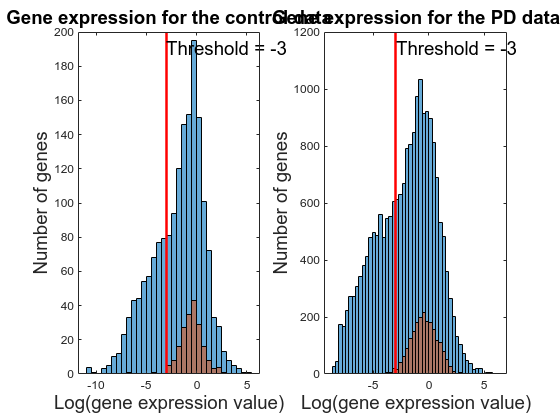

% load transcriptomic data
TransData='control data';
% TransData='PD data';
dataFile='~/drive/bioenergeticsPD/data/snRNA-seq/GSE178265/CellXgene';
if any(strfind(TransData,'PD'))
    transcriptomicData = readtable([dataFile filesep 'DNpd_NBnew.csv']);
else
    transcriptomicData = readtable([dataFile filesep 'DNcontrol_NBnew.csv']);   
end
transcriptomicData(~ismember(string(transcriptomicData.genes),string(modelGenes)),:)=[];

subplot(1,2,1)
histogram(log(transcriptomicData.expVal))
ylim = get(gca, 'ylim');
hold on
histogram(log(transcriptomicData.expVal(ismember(transcriptomicData.EnsembleID,houseKeepGenes.GeneID))))

transcriptomicThreshold = -3;
line([transcriptomicThreshold transcriptomicThreshold], [ylim(1) ylim(2)], 'color', 'r', 'LineWidth', 2);
t = text(transcriptomicThreshold, ylim(2) - (ylim(2) * 0.05), ['Threshold = ',char(string(transcriptomicThreshold))]);
t.FontSize = 14;
hold off
title(['Gene expression for the ', TransData],FontSize= 14)
ylabel('Number of genes',FontSize= 14)
xlabel('Log(gene expression value)',FontSize= 14)
% load transcriptomic data
% TransData='control data';
TransData='PD data';
dataFile='~/drive/bioenergeticsPD/data/snRNA-seq/GSE178265/CellXgene';
if any(strfind(TransData,'PD'))
    transcriptomicData = readtable([dataFile filesep 'DNpd_NBnew.csv']);
else
    transcriptomicData = readtable([dataFile filesep 'DNcontrol_NBnew.csv']);   
end
subplot(1,2,2)
histogram(log(transcriptomicData.expVal))
ylim = get(gca, 'ylim');
hold on
histogram(log(transcriptomicData.expVal(ismember(transcriptomicData.EnsembleID,houseKeepGenes.GeneID))))

transcriptomicThreshold = -3;
line([transcriptomicThreshold transcriptomicThreshold], [ylim(1) ylim(2)], 'color', 'r', 'LineWidth', 2);
t = text(transcriptomicThreshold, ylim(2) - (ylim(2) * 0.05), ['Threshold = ',char(string(transcriptomicThreshold))]);
t.FontSize = 14;
hold off
title(['Gene expression for the ', TransData],FontSize= 14)
ylabel('Number of genes',FontSize= 14)
xlabel('Log(gene expression value)',FontSize= 14)